#### ** Here we see the filter bank as designed by** ***C. Li, C. Zheng, and C. Tai, “Detection of ECG characteristic points using wavelet transforms,” IEEE Trans. Biomed. Eng., vol. 42, pp. 21–28, Jan. 1995"***

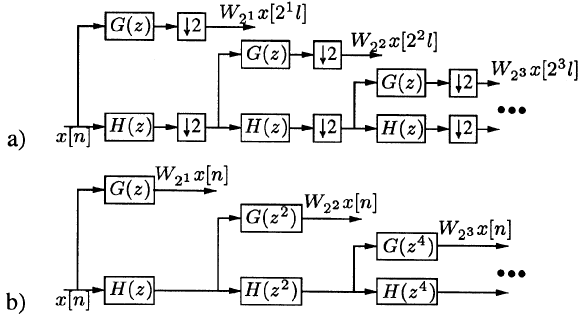

Two filter-bank implementations: a) Mallat's algorithm  b) Algorithm a trous.

Ofcourse we will utilize algorithm a trous.

We will operate on qtdb database sampled at 250Hz

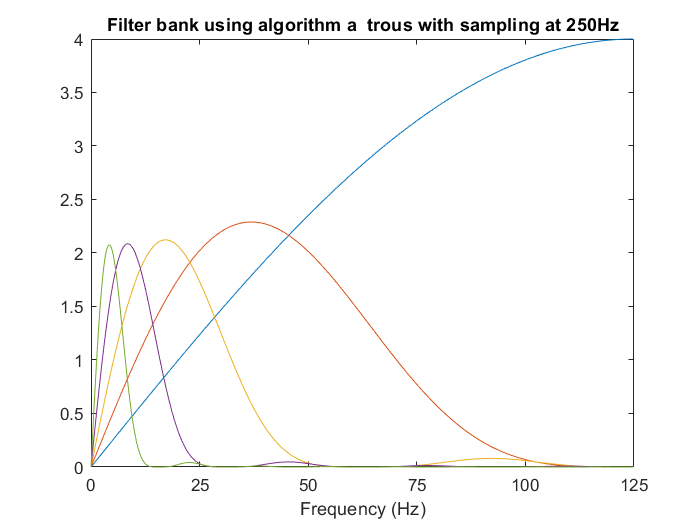

if(count1==0)
    [record,a,b,c,d,e] = rdann('qtdb/sel02','pu0');
    [sig, Fs, tm] = rdsamp('qtdb/sel02', 1);
    count1=count1+1
end

fs = 250;
Gz = 2*[1 -1];
Hz = 1/8*[1 3 3 1];
level = 5;
G = {};
H = {};
G{1} = Gz;
H{1} = Hz;
for i = 1:level
    G{i+1} = upsample(Gz,2^i) ;
    H{i+1} = upsample(Hz,2^i) ; 
end

W{1} = G{1};
for i = 2:level
    temp = G{i};
    for j = 1:(i-1)
        temp = conv(temp , H{j});
    end
    W{i} = temp;
end
W{2}(end)=[];
for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*125/pi;
    plot(q,abs(h));
    hold on
end
title 'Filter bank using algorithm a  trous with sampling at 250Hz'
xlabel 'Frequency (Hz)'
xlim([0,125])
xticks([0,25,50,75,100,125])

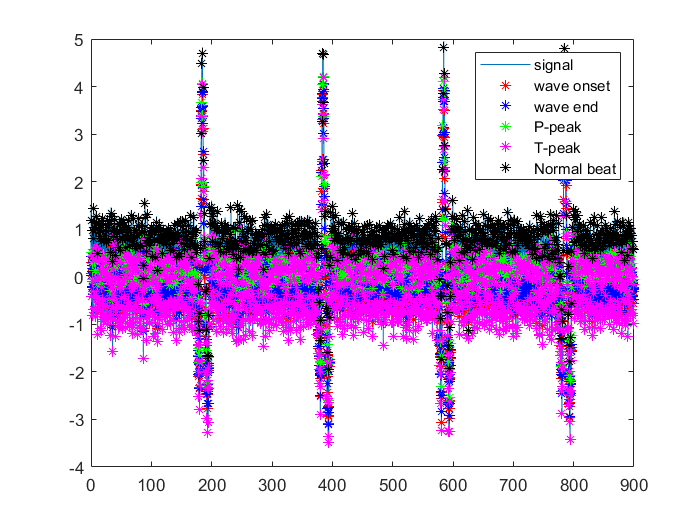

t=tm;
figure
plot(t,sig,t(record(find(a=='('))),sig(record(find(a=='('))),'r*');
hold on
plot(t(record(find(a==')'))),sig(record(find(a==')'))),'b*');
plot(t(record(find(a=='p'))),sig(record(find(a=='p'))),'g*');
plot(t(record(find(a=='t'))),sig(record(find(a=='t'))),'m*');
plot(t(record(find(a=='N'))),sig(record(find(a=='N'))),'k*');
legend('signal','wave onset','wave end','P-peak','T-peak','Normal beat')

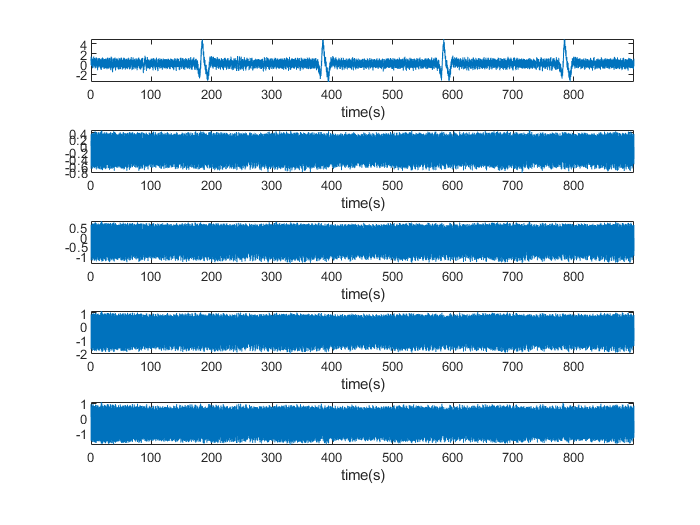

x=sig;
record_temp=record(find(a=='N'));
figure
w1 = filter(W{1},[1],x);
w2 = filter(W{2},[1],x);
w3 = filter(W{3},[1],x);
w4 = filter(W{4},[1],x);

delay1=round(mean(grpdelay(W{1})));
delay2=round(mean(grpdelay(W{2})));
delay3=round(mean(grpdelay(W{3})));
delay4=round(mean(grpdelay(W{4})));
x=x(1:end-delay4);
t=t(1:end-delay4);

w1(1:delay1)=[];
w1=w1(1:end-delay4+delay1);
w2(1:delay2)=[];
w2=w2(1:end-delay4+delay2);
w3(1:delay3)=[];
w3=w3(1:end-delay4+delay3);
w4(1:delay4)=[];
figure()
subplot(5,1,1)
plot(t,x)
axis tight
xlabel 'time(s)'
subplot(5,1,2)
plot(t,w1)
xlabel 'time(s)'
axis tight
subplot(5,1,3)
plot(t,w2)
xlabel 'time(s)'
axis tight
subplot(5,1,4)
plot(t,w3)
axis tight
xlabel 'time(s)'
subplot(5,1,5)
plot(t,w4)
axis tight
xlabel 'time(s)'

Now we move to peak detection

length = 2^10;
steps=ceil(size(x,1)/length)

steps = 220

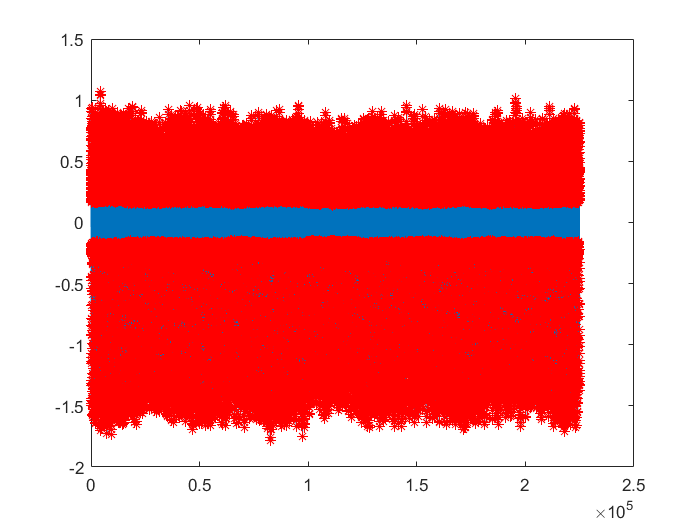

n4k=[];
n3k=[];
n2k=[];
n1k=[];
for i = 1:size(w4,1)
    e_4_QRS=rms(w4(max(i-length,1):min(size(w4,1),i+length)));
    if(abs(w4(i))>0.5*e_4_QRS)
        n4k=[n4k;i];
        e_3_QRS=rms(w3(max(i-length,1):min(size(w3,1),i+length)));
        set_3=abs(w3(max(1,i-5):min(i+5,size(w3,1))));
        if(max(set_3)>e_3_QRS)
            [val,max_pos]=max(set_3);
            n3k=[n3k;max(1,i-5)+max_pos-1];
            e_2_QRS=rms(w2(max(i-length,1):min(size(w2,1),i+length)));
            set_2=abs(w2(max(1,i-7):min(i+7,size(w2,1))));
            if(max(set_2)>e_2_QRS)
                [val,max_pos]=max(set_2);
                n2k=[n2k;max(1,i-7)+max_pos-1];  
                e_1_QRS=rms(w1(max(i-length,1):min(size(w1,1),i+length)));
                set_1=abs(w1(max(1,i-10):min(i+10,size(w1,1))));
                if(max(set_1)>e_1_QRS)
                    [val,max_pos]=max(set_1);
                    n1k=[n1k;max(1,i-10)+max_pos-1];   
                else
                    n1k=[n1k;0];
                end
            else
                n2k=[n2k;0];
                n1k=[n1k;0];
            end
        else
            n3k=[n3k;0];
            n2k=[n2k;0];
            n1k=[n1k;0];
        end
        
    end
end

figure
plot(t*250,w4,t(n4k)*250,w4(n4k),'r*')

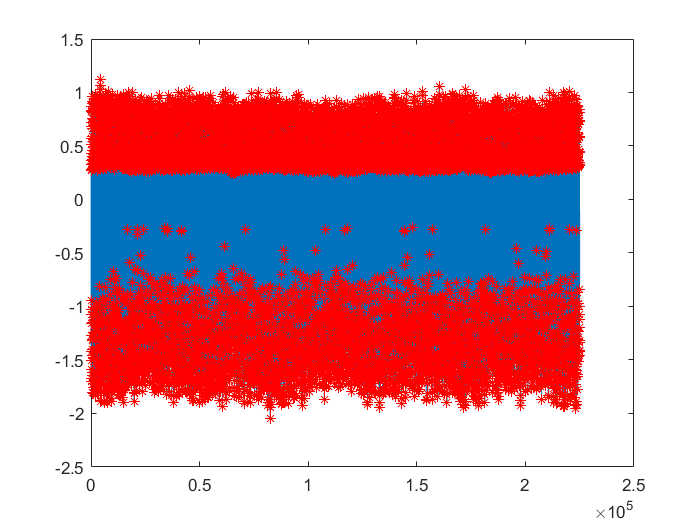

n3k=n3k.*(n1k~=0);
n3k(find(n3k==0))=[];
figure
plot(250*t,w3,250*t(n3k),w3(n3k),'r*')

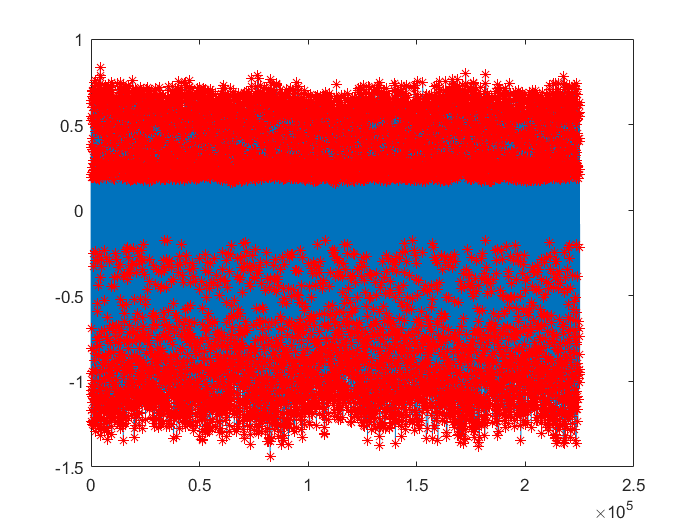

n2k=n2k.*(n1k~=0);
n2k(find(n2k==0))=[];figure
plot(250*t,w2,250*t(n2k),w2(n2k),'r*')

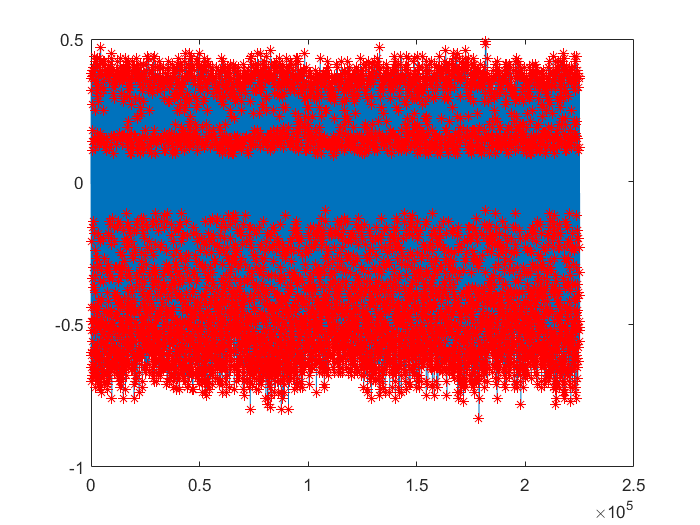

n1k(find(n1k==0))=[];
figure
plot(250*t,w1,250*t(n1k),w1(n1k),'r*')

n1k=unique(n1k);

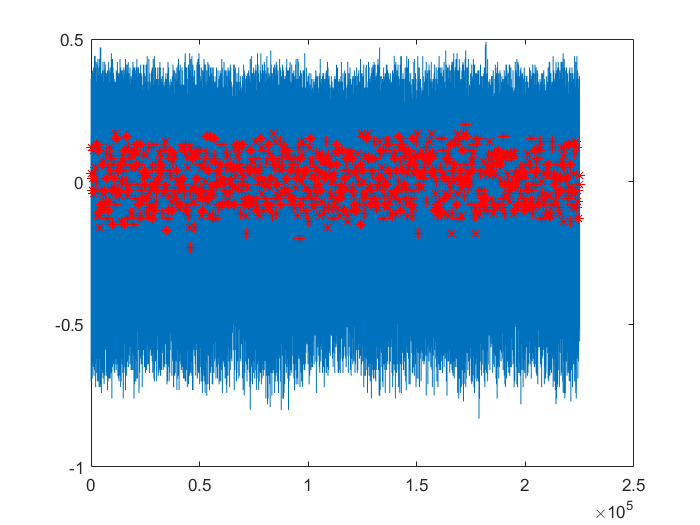

R=[];
for i = 1:size(n1k)-1
    if(w1(n1k(i))*w1(n1k(i+1))<0 & (n1k(i+1)-n1k(i))<20)
       piece = abs(w1(n1k(i):n1k(i+1)));
       [junk,pos] = min(piece);
       R=[R;n1k(i)-1+pos];
    end
end
count=1;
while count<size(R,1)
    if((R(count+1)-R(count))<30)
            R(count+1)=[];
            count=count+1;
    else
        count=count+1;
    end
end
figure
plot(250*t,w1,250*t(R),w1(R),'r*')

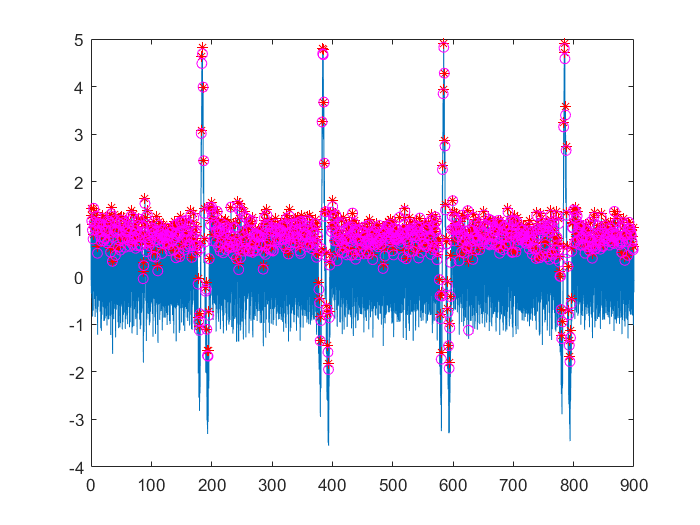

figure
plot(t,x,t(R),x(R),'r*',t(record_temp),x(record_temp),'mo')

true_positive=0;
false_negative=0;
for i = 1:size(record_temp,1)
    if(min(abs(record_temp(i)-R))<5)
        true_positive=true_positive+1;
    else
        false_negative=false_negative+1;
    end
end
false_positive=0;
for i = 1:size(R,1)
    if(min(abs(R(i)-record_temp))>4)
        false_positive=false_positive+1;
    end
end
true_positive

true_positive = 883

false_negative

false_negative = 1

false_positive

false_positive = 3

se=true_positive/(true_positive+false_negative)*100

se = 99.8869

p=true_positive/(true_positive+false_positive)*100

p = 99.6614

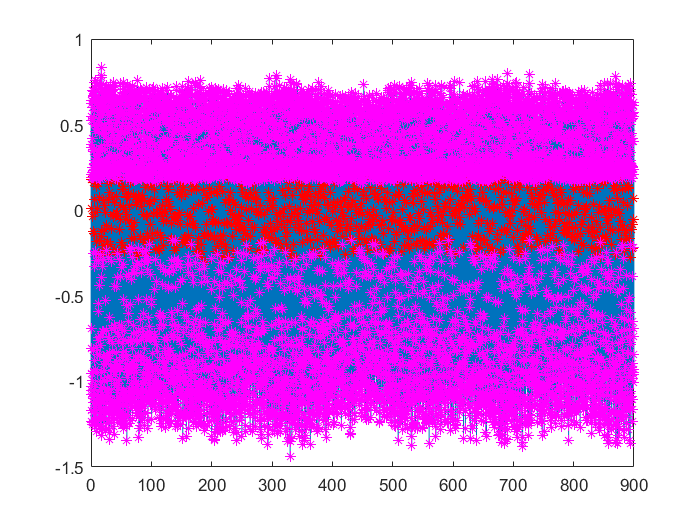

plot(t,w2,t(R),w2(R),'r*',t(n2k),w2(n2k),'m*')

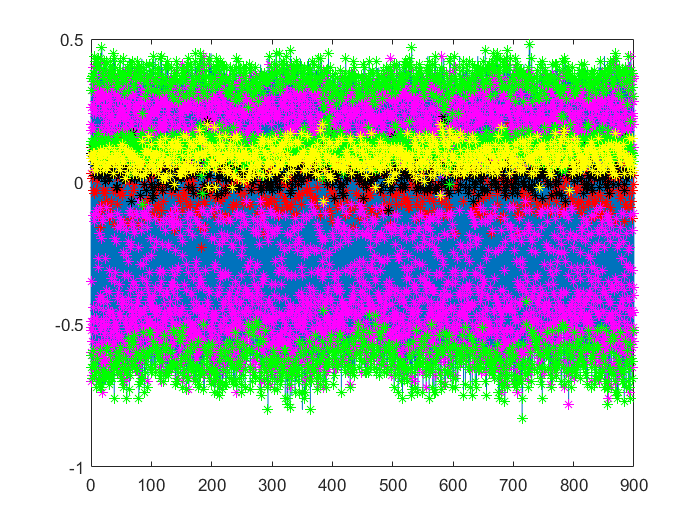

Repo=R;
Q=[];
S=[];
maxima_post=[];
maxima_pre=[];
qq=size(Repo,1);
for i = 1:qq-1
    window_min = Repo(i)-50;
    window_max = Repo(i)+50;
    rr_wave_pre = abs(w2(window_min:Repo(i)));
    rr_wave_post = abs(w2(Repo(i):window_max));
%     rr_wave_pre = rr_wave_pre.*(rr_wave_pre>0.06*max([rr_wave_pre;rr_wave_post]));
%     rr_wave_post = rr_wave_post.*(rr_wave_post>0.09*max([rr_wave_pre;rr_wave_post]));    
    idx_pre = find((islocalmax(rr_wave_pre)>0) & (rr_wave_pre>0.06*max([rr_wave_pre;rr_wave_post])),2,'last');
    idx_post = find((islocalmax(rr_wave_post)>0) & (rr_wave_post>0.09*max([rr_wave_pre;rr_wave_post])),2,'first');
    maxima_post=[maxima_post;idx_post+Repo(i)-1];
    maxima_pre=[maxima_pre;idx_pre+Repo(i)-50-1];

    if(size(idx_post,1)>1)
    rr_wave_post=w1((Repo(i)+idx_post(1)-2):(Repo(i)+idx_post(2)));
    [junk, idx] = min(abs(rr_wave_post));
    S=[S;idx+Repo(i)+idx_post(1)-2]; 
    end
    if(size(idx_post,1)>1)
    rr_wave_pre=w1((Repo(i)-50+idx_pre(1)-2):(Repo(i)-50+idx_pre(2)));
    [junk, idx]= min(abs(rr_wave_pre));
    Q=[Q;idx+Repo(i)-50+idx_pre(1)-2];
    end
end
plot(t,w1,t(R),w1(R),'r*',t(n2k),w1(n2k),'m*',t(Q),w1(Q),'k*',t(maxima_pre),w1(maxima_pre),'g*',t(maxima_post),w1(maxima_post),'g*',t(S),w1(S),'y*')